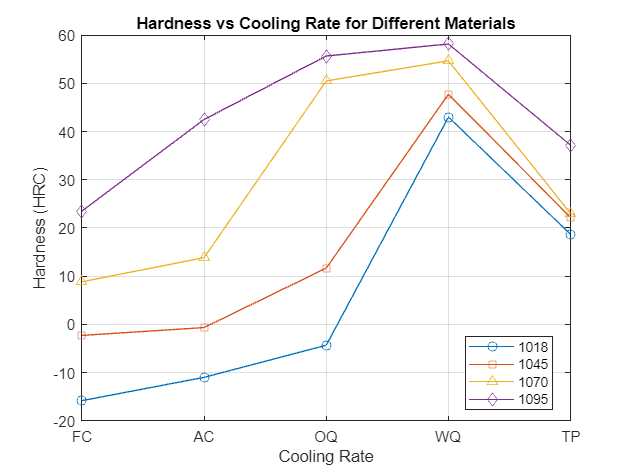

% This algorithm plots Hardness vs Cooling Rate and Hardness vs Carbon
% Content for various types of steel
% ATTRIBUTION: algorithm was written by myself, with the help of
% ChatGPT to determine how to filter and sort data values for plotting
% Mathworks.com for MATLAB syntax

% The CSV file is too much of a hassle to sort through, it's faster and
% easier to manually enter the data into MATLAB using matrices
FC1018 = [-15.5,-15,-17];
FC1045 = [-3,-3.4,-0.5];
FC1070 = [9,9,8.5];
FC1095 = [23,24,23.5];

AC1018 = [-13,-9,-11];
AC1045 = [-2,-2,2];
AC1070 = [12,11.5,18];
AC1095 = [42.5,42,43];

OQ1018 = [-10,-2,-1];
OQ1045 = [16,17,2];
OQ1070 = [50.5,50,51];
OQ1095 = [55,57,55];

WQ1018 = [40,44,45];
WQ1045 = [46.1,47.1,50];
WQ1070 = [54,55,55];
WQ1095 = [58,58.5,58];

TP1018 = [19,18,19];
TP1045 = [19.5,23,24];
TP1070 = [21,24,24];
TP1095 = [37.5,37,37];

% Take the data from each matrix to create the hardness values for plotting
hardness1018 = [mean(FC1018),mean(AC1018),mean(OQ1018),mean(WQ1018),mean(TP1018)];
hardness1045 = [mean(FC1045),mean(AC1045),mean(OQ1045),mean(WQ1045),mean(TP1045)];
hardness1070 = [mean(FC1070),mean(AC1070),mean(OQ1070),mean(WQ1070),mean(TP1070)];
hardness1095 = [mean(FC1095),mean(AC1095),mean(OQ1095),mean(WQ1095),mean(TP1095)];

hardnessFC = [mean(FC1018),mean(FC1045),mean(FC1070),mean(FC1095)];
hardnessAC = [mean(AC1018),mean(AC1045),mean(AC1070),mean(AC1095)];
hardnessOQ = [mean(OQ1018),mean(OQ1045),mean(OQ1070),mean(OQ1095)];
hardnessWQ = [mean(WQ1018),mean(WQ1045),mean(WQ1070),mean(WQ1095)];
hardnessTP = [mean(TP1018),mean(TP1045),mean(TP1070),mean(TP1095)];

carbon = [0.18, 0.45, 0.70, 0.95];


% Create a new figure for plotting
figure;

% Plot the hardness values with cooling rate
plot(hardness1018, '-o', 'DisplayName', '1018');
hold on;
plot(hardness1045, '-s', 'DisplayName', '1045');
plot(hardness1070, '-^', 'DisplayName', '1070');
plot(hardness1095, '-d', 'DisplayName', '1095');
hold off;

% Add labels, legend, and grid
set(gca, 'xtick', 1:5, 'xticklabel', {'FC', 'AC', 'OQ', 'WQ', 'TP'});
xlabel('Cooling Rate');
ylabel('Hardness (HRC)');
title('Hardness vs Cooling Rate for Different Materials');
legend('1018', '1045', '1070', '1095', 'Location', 'Best')
grid on;

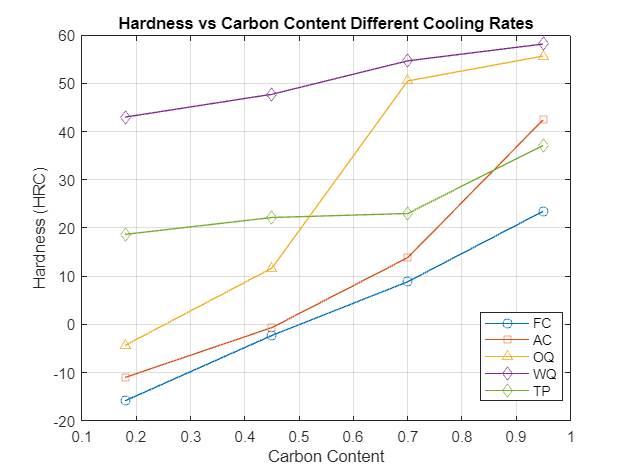


%Plot the hardness values with %carbon content
plot(carbon, hardnessFC, '-o', 'DisplayName', 'FC');
hold on;
plot(carbon, hardnessAC, '-s', 'DisplayName', 'AC');
plot(carbon, hardnessOQ, '-^', 'DisplayName', 'OQ');
plot(carbon, hardnessWQ, '-d', 'DisplayName', 'WQ');
plot(carbon, hardnessTP, '-d', 'DisplayName', 'TP');
hold off;

% Add labels, legend, and grid
xlabel('Carbon Content');
ylabel('Hardness (HRC)');
title('Hardness vs Carbon Content for Different Cooling Rates');
legend('FC', 'AC', 'OQ', 'WQ','TP', 'Location', 'Best')
grid on;